## How can you determine the stability of a building during an earthquake?

Buildings of different size and composition will naturally oscillate at different frequencies. Small buildings tend to oscillate quickly, while larger buildings oscillate more slowly.

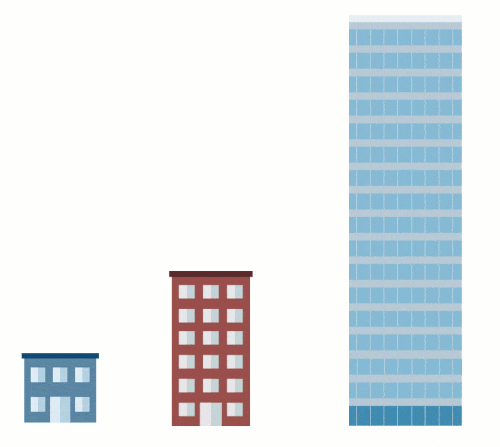

In this script, you'll learn how to construct a multiple mass-spring-damper model in Simulink. Afterward, you'll apply that model to examine the resonance frequencies of a simulated building modeled by 20 connected mass-spring-dampers. 

# The Multiple Mass-Spring-Damper System

clear % This clears the MATLAB workspace each time you run the script
addModelPaths % This helper adds the model paths

 Run this section to add the folder that contains the models to the MATLAB Search Path.

## 1. Writing a system of differential equations in matrix form

When handling large systems of differential equations, it is often preferable to write them in matrix form. The properties of the resulting matrices (such as their eigenvalues) offer insights into the system's dynamics.

** Exercise.** Consider the double mass-spring-damper system:

    
$$m_1 \ddot{x}_1 = F_1 + k_2(x_2 - x_1) + c_2 (\dot{x}_2 - \dot{x}_1) - k_1 x_1 - c_1 \dot{x}_1$$


    
$$m_2 \ddot{x}_2 = F_2 - k_2(x_2 - x_1) - c_2 (\dot{x}_2 - \dot{x}_1)$$


Write this system of equations in the matrix form:

    
$$M \ddot{ \mathbf{x} } = C \dot{\mathbf{x}} + K \mathbf{x} + F$$


using the vector solution variable

    $\mathbf{x}= \left[ \matrix{ x_1 \cr x_2  } \right]$.

When complete, type your matrices below in terms of the defined symbolic variables.

syms m_1 m_2 k_1 k_2 c_1 c_2 F_1 F_2
% Replace the NaNs with the correct matrix elements in terms of the defined symbolic variables 
M = [m_1 0; 0 m_2];
C = [-c_1-c_2, c_2; c_2, -c_2];
K = [-k_2-k_1, k_2; k_2, -k_2];
F = [F_1; F_2];

checkMatrices(M,C,K,F)  % This helper function (located at the bottom of the script) checks your matrices

## 2. Vectorize the double mass-spring-damper model in Simulink

While the matrix form of the differential equation system is useful for many purposes, there is a simpler way to vectorize the system for solution in Simulink. For this purpose, you can define vectors.

    
$$\mathbf{x}= \left[ \matrix{ x_1 \cr x_2  } \right]$$
    
$$\mathbf{c}= \left[ \matrix{ c_1 \cr c_2  } \right]$$
    
$$\mathbf{k}= \left[ \matrix{ k_1 \cr k_2  } \right]$$
    
$$\mathbf{F}= \left[ \matrix{ F_1 \cr F_2  } \right]$$


You can use these definitions to create a simple vectorization of the model in Simulink, without having to define matrices.

** Exercise. **In this exercise, you will vectorize the* double* mass-spring-damper model.

1. Open the Simulink model [msdDoubleVectorized.slx](matlab: open_system('models/msdDoubleVectorized')). Notice that the constant vectors are already defined.

2. You can vectorize a Simulink model by defining signals to be vectors, rather than single values. Open the [MATLAB Function block](matlab: hilite_system('msdDoubleVectorized/doubleMassSpringDamper'); pause(1); hilite_system('msdDoubleVectorized/doubleMassSpringDamper','none');) and replace the function interface so that it uses vector variable names as shown below.

3. Besides modifying the interface, you need to replace the underscore index on each variable with an index into the correct element of the vector. For example, replace `x_ddot_1 `with `x_ddot(1)`. Perform this replacement for all indices (Hint: use find/replace. Access this with Ctrl+F).

4. You must define the output variable `x_ddot` at the start of the function. Use `x_ddot = zeros(2,1);` to define it as a two row vector.

5. With the MATLAB function block vectorized, you can complete the Simulink model. Connect the signals in the model so that it is integrated by the two integral blocks already in the model. 

6. Run the simulation. If your model is correctly vectorized, you should see the output shown.

            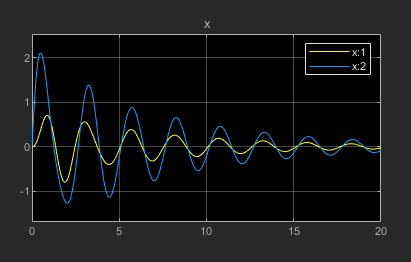

*            Solution to the double mass-spring-damper system*

Having trouble? Take a look at the completed model: [msdDoubleVectorizedSoln.slx](matlab: open_system('models/msdDoubleVectorizedSoln')).

## 3. The multiple mass-spring-damper model

The multiple mass-spring-damper model couples $n$ mass-spring-dampers into a single system. This system has $n$ degrees of freedom (n-DOF): $x_1, \ x_2$, $\ldots$, $x_n$.

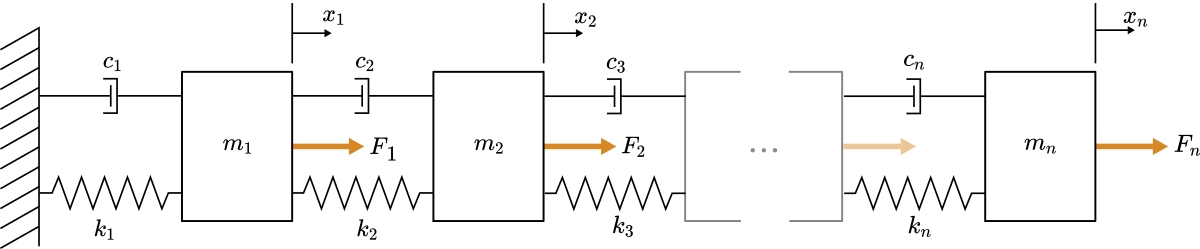

*Schematic of a multiple mass-spring-damper system*

The parameters are the same as for the smaller mass-spring-damper models:

- $k_i$: spring stiffness of the $i^{th}$ spring [N/m]

- $c_i$: damping of the $i^{th}$ damper [N$\cdot$s/m]

- $m_i$: mass of the $i^{th}$ mass [kg]

- $F_i$: externally applied force on the $i^{th}$ mass [N] (can be constant or time dependent: $F(t)$)

The time-dependent behavior of the system is solved for using the variables: 

- $t$: time since start of simulation [s]

- $\mathbf{x}= [ x_1, x_2 , \ldots, x_n  ]^\top$: vector of time-dependent ($x_i=x_i(t)$) displacement of the masses from the reference equilibrium positions [m]

 ** Try**

- On paper, draw free body diagrams of the forces acting on: the first mass $m_1$, the $i^{th}$ middle mass $m_i$, and the last mass $m_n$.

- After drawing the free body diagram, apply Newton's second law to derive the equations of motion for each of those three masses.

                $m_1\ddot{x}_1 \;=\;\;\sum Forces$   and   $m_2\ddot{x}_2 \;=\;\;\sum Forces$.

showSolutionFBD = true; % Click the checkbox to view the solution
if(showSolutionFBD)
    I = imread("images/FBDMultipleMSD.png");
    imshow(I);
end

## 3. Simulink multiple mass-spring-damper model

The equations of motion for the n-DOF mass-spring-damper system derived in the previous section are

    
$$m_1 \ddot{x}_1 = F_1 + k_2(x_2 - x_1) + c_2 (\dot{x}_2 - \dot{x}_1) - k_1 x_1 - c_1 \dot{x}_1$$


            
$$\vdots$$


    
$$m_i \ddot{x}_i =   F_i +  k_{i+1} ( x_{i+1} - x_{i}) + c_{i+1}(\dot{x}_{i+1} - \dot{x}_{i})   -  k_i ( x_i - x_{i-1})  - c_i(\dot{x}_i - \dot{x}_{i-1})$$


            
$$\vdots$$


    
$$m_n \ddot{x}_n =   F_n  -  k_n ( x_n - x_{n-1})  - c_n(\dot{x}_n - \dot{x}_{n-1})$$


** Challenge exercise. **This exercise is only meant for experienced MATLAB users. If this does not apply to you, you should skip this exercise. 

- Open the model [msdMultiple.slx](matlab: open_system('models/msdMultiple')). This model has been only partially updated from the vectorized double mass-spring-damper. Edit the code inside the MATLAB Function block to implement the multiple mass-spring-damper equations shown above with $n = 8$. You should define $n$ inside the MATLAB Function block (not as an input).

- When you're finished, compare your result to the completed model: [msdMultipleSoln.slx](matlab: open_system('models/msdMultipleSoln')). Is your model equivalent? 

- Complete the next task using both your model and the solution. Do the solutions match?

 ** Task**

- Open the Simulink model [msdMultipleSoln.slx](matlab: open_system('models/msdMultipleSoln')). Notice that the model constants are defined in terms of variables. These are not defined in the model, so you need to define them before running the model. Run this section of live script code to define the parameters.

**Model parameter definitions**

n = 8; % The number of mass-spring-dampers
F = 0*ones(n,1); % The applied force vector
c = 0.5*ones(n,1); % The damping coefficient vector
k = 10*ones(n,1); % The spring stiffness vector
m = 5*ones(n,1); % Vector of masses
x_dot_0 = 0*ones(n,1); % Initial condition of x_dot
x_0 = 0*ones(n,1); % Initial condition of x

% Modify individual values in the parameter vectors
x_dot_0(1) = 5; 

- Try running the model and viewing the output of the [scope](matlab: hilite_system('msdMultipleSoln/Scope'); pause(1); hilite_system('msdMultipleSoln/Scope','none');).

- Open the [MATLAB Function block](matlab: hilite_system('msdMultipleSoln/multiple mass-spring-damper'); pause(1); hilite_system('msdMultipleSoln/multiple mass-spring-damper','none');) for the multiple mass-spring-damper and observe the implementation of the equations of motion. These equations have been implemented in the MATLAB Function block using vector indexing. You could also implement the middle set of equations using a for loop.

**Visualize the model output **

You can visualize the Simulink model output in MATLAB. Run this section of code to visualize the motion of the mass-spring-dampers. Before running this section, ensure that the model parameters have been defined (by running the previous section).

steps = 150; % The number of steps used in the visualization
visualize = true; % Click the checkbox to show the visualization
if(visualize)
    simOut = sim("models/msdMultipleSoln"); % Runs the Simulink model
    animateMSD(simOut.tout,simOut.yout,1,steps) % Calls a helper function (located at the bottom of this script) to create the animation
end

 **Reflect:**

- There are two main oscillation frequencies in the simulated system. Which part of the system causes each vibration?

- What is the period of the faster oscillation? What is the period of the slower oscillation?

- Try running the model for 100 seconds and visualize the output. How do the oscillations change over time?

## 4. Spectral analysis of the multiple mass-spring-damper

To better understand a vibrating system, it is useful to analyze its characteristics in the frequency domain. In this section, you'll use the discrete Fourier transform to analyze the frequency domain response of the simulated multiple mass-spring-damper system. 

** Exercise.** Compute the power spectrum of $x_1(t)$ using the Spectrum Analyzer.

**Task 1**. Open the Simulink model [msdMultipleFreq.slx](matlab: open_system('models/msdMultipleFreq')) and set the stop time to 500s. Increasing the duration of the simulation improves the resolution of the power spectrum.

**Task 2**. Reset the default parameters by double-clicking the parameter value text inside the model.

**Task 3**. To compute the power spectrum, three blocks are required. Add them to the Simulink model as illustrated.

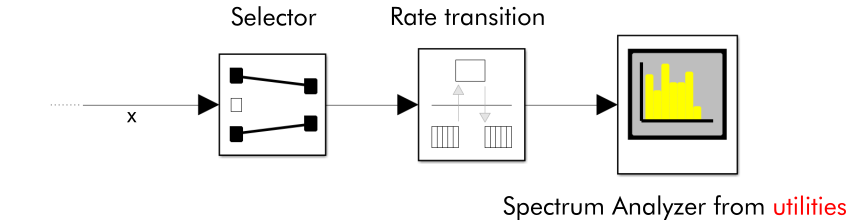

- Add a [Selector block](https://www.mathworks.com/help/simulink/slref/selector.html) from the **Simulink / Signal Routing** library. This is used to select one of the eight solution variables.

- Add a [Rate Transition block](https://www.mathworks.com/help/simulink/slref/ratetransition.html). This is used to convert the signal to a fixed time step necessary for computing the discrete Fourier transform.

- Add a Spectrum Analyzer block from the **Simscape** **Utilities library. **Do **not **use the spectrum analyzer from any of the other toolboxes. The other spectrum analyzer blocks have similar functionality but are initially set to look at responses in different frequency ranges. If you select the wrong block, the output will not appear as shown below.

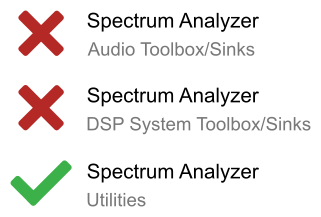

*Make sure you select the appropriate Spectrum Analyzer block!*

**Task 4. **Connect the blocks as shown. The input signal should be the solution signal: $\mathbf{x}$. Then, set the following inside the block dialogues:

- In the Selector block, set the Index to `1 `(this selects $x_1$ from the solution vector $\mathbf{x}$) and Input Port Size to `8` (the number of variables in the solution vector $\mathbf{x}$).

- In the Rate Transition block, set the Output port sample time to 0.05. This sampling frequency is good for capturing the low-frequency oscillations present in this model.

**Task 5.** Run the model and observe the output in the Spectrum Analyzer. Zoom in on the region between 0 and 1 Hz where most of the spectral content is located. If correct, you should see the plot below.

            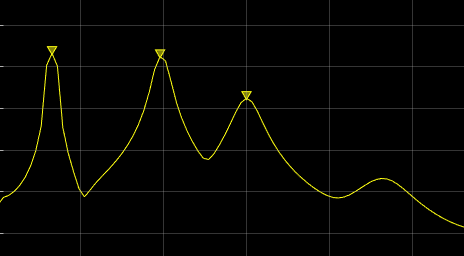

            *Power spectrum at low frequencies (< 1Hz)*

Having trouble? Take a look at the completed model: [msdMultipleFreqSoln.slx](matlab: open_system('models/msdMultipleFreqSoln')).

**Task 6. **Use the [Peak Finder](https://www.mathworks.com/help/simulink/ug/peak-finder-panel.html) (Tools > Measurements > Peak Finder) to find the three peaks as shown. Type the frequencies of the three major peaks found below.

peakFrequencies = [0.065 0.195 0.299]; % Replace the NaNs with the frequencies (in Hz)
checkFrequencies(peakFrequencies)

 **Reflect:**

- Compute the period of the three frequencies measured above. Then, look at the graph of $x_1$ in the scope. Can you find the oscillations that correspond to each of these periods?

## 5. Identify the resonant frequencies in a building model

In this section, you will simulate a building model and use the power spectrum to identify its natural oscillation periods. To reduce the complexity, simplifying assumptions are made:

- The walls are assumed to be flexible and massless. 

- The floors are assumed to be rigid masses connected by spring-dampers (the walls). 

- Only horizontal motion is modeled.

- The parameters have been rescaled to $m=1$ and are treated as unitless. These parameters were not selected to reflect the mass or stiffness of a real structure. Instead, they were selected to produce realistic oscillation frequencies.

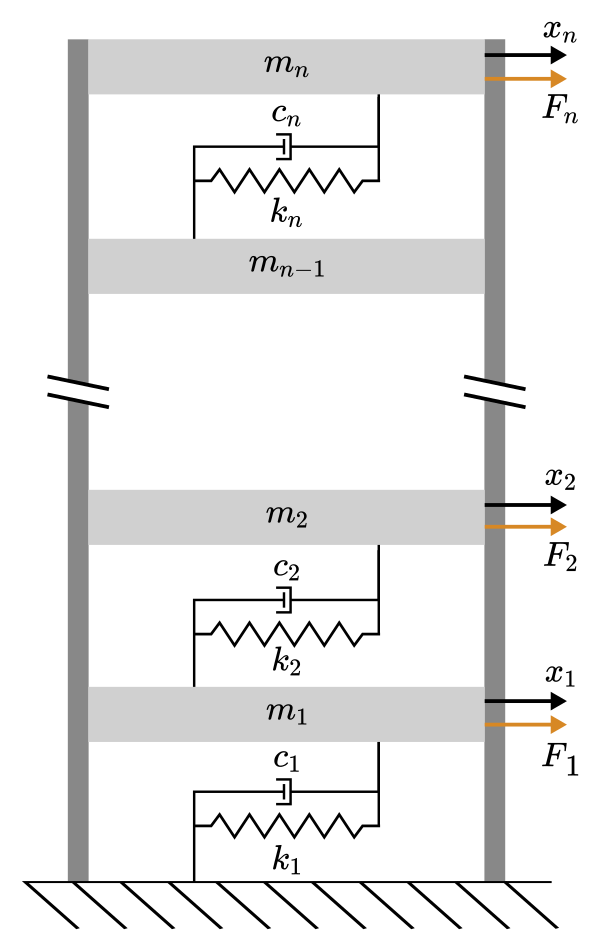

*Mass-spring-damper building model*

** Exercise.** Identify the resonant frequencies of the mass-spring-damper building model.

**Task 1**. Open the Simulink model [msdMultipleBuilding.slx](matlab: open_system('models/msdMultipleBuilding')), which models a building with 20 floors.

**Task 2**. This model has 20 degrees of freedom, so the constant vectors and initial values of the system must be constructed to match. Run this section to populate the parameters. Note that the building is given an initial offset in the initial condition `x_dot_0`.

n = 20; % The number of mass-spring-dampers

c = 10*ones(n,1); % The damping coefficient vector
k = 1100*ones(n,1); % The spring stiffness vector
m = 1*ones(n,1); % Vector of masses
x_dot_0 = 0*ones(n,1); % Initial condition of x_dot
x_0 = 0*ones(n,1); % Initial condition of x

% Modify individual values in the parameter vectors
x_dot_0(1) = 1; 

**Task 3. **Set the Index in the Selector block to 20 so that the spectrum is measured for $x_{20}$, the displacement of the 20th floor. Set the forcing magnitude ([F0](matlab: hilite_system('msdMultipleBuilding/F0'); pause(1); hilite_system('msdMultipleBuilding/F0','none');)) to zero and the simulation stop time to 200.

**Task 4**. Run the model and use the peak finder tool in the Spectrum Analyzer block to identify the prominent frequencies. Record the *period* of oscillation for the two most prominent peaks below. Recall that the period $T = 1/f$, where $f$ is the frequency.

T = [ 2.47, 0.83]; % Replace NaN with the calculated periods
checkPeriod(T);

 ** Try**

- Set the initial conditions to zero by running this section.

x_dot_0 = 0*ones(n,1); % Initial condition of x_dot
x_0 = 0*ones(n,1); % Initial condition of x

- The model contains a subsystem ([F1](matlab: hilite_system('msdMultipleBuilding/F1'); pause(1); hilite_system('msdMultipleBuilding/F1','none');)) that produces a periodic forcing $F_1 \left(t\right)=F_0 \;\sin \left(\frac{2\pi t}{T}\right)\;\;$ while $t_s < t < t_f$ and 0 otherwise. The forces on the other masses are zero. Set the period, [T](matlab: hilite_system('msdMultipleBuilding/T [s]'); pause(1); hilite_system('msdMultipleBuilding/T [s]','none');), of the forcing to the strongest resonant period and the amplitude ([F0](matlab: hilite_system('msdMultipleBuilding/F0'); pause(1); hilite_system('msdMultipleBuilding/F0','none');)) to $F_0 = 1$ and observe if there is a resonant response.  

- Try setting the periodicity of the forcing to T = 1.5 s. Is the response reduced?

- Try setting the periodicity of the forcing to the second natural period that you measured. Is there a resonant response?

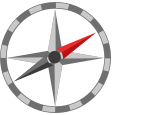**Further exploration**

Spectral analysis can be used to identify vibration modes present in many different physical systems. To learn more about spectral analysis and its applications, visit the documentation pages linked below.

- [Estimate the Power Spectrum in Simulink](https://www.mathworks.com/help/dsp/ug/estimate-the-power-spectrum-in-simulink.html): an introduction to spectral analysis in Simulink

- [Water Hammer Effect](https://www.mathworks.com/help/physmod/simscape/ug/water-hammer-effect.html): a spectral analysis of the water hammer effect in a pipe system model

**Helper functions**

These functions check answers and generate animations.

function correct = isEqualCheckCustom(userSubmission,correctAnswer,correctResponse,incorrectResponse)
    correct = true;
    if( isequal(userSubmission, correctAnswer) )
        disp(correctResponse)
    else
        warning(incorrectResponse)
        correct = false;
    end
end

function checkFrequencies(peakFrequenciesUser)
    pu = sort(peakFrequenciesUser);
    p = [0.065 0.195 0.299];
    if(sum(abs(p-pu)) < 0.002 )
        disp("Correct!")
    else
        warning("Incorrect. Use the peak finder tool.") 
    end
end

function checkPeriod(Tuser)
    T = [ 2.4752, 0.8258];
    if(sum(abs(T-Tuser)) < 0.01 )
        disp("Correct!")
    else
        warning("Incorrect. Use the peak finder tool.") 
    end
end

function checkMatrices(Muser, Cuser, Kuser, Fuser)
    syms m_1 m_2 k_1 k_2 c_1 c_2 F_1 F_2
    M = [m_1 0; 0 m_2];
    C = [-c_1-c_2, c_2; c_2, -c_2];
    K = [-k_2-k_1, k_2; k_2, -k_2];
    F = [F_1; F_2];
    
    isEqualCheckCustom(Muser,M,"M Correct","M Incorrect");
    isEqualCheckCustom(Cuser,C,"C Correct","C Incorrect");
    isEqualCheckCustom(Kuser,K,"K Correct","K Incorrect");
    isEqualCheckCustom(Fuser,F,"F Correct","F Incorrect");
end

function animateMSD(tin, xin, spacingMultiplier, steps)
    
    Nmass = size(xin,2); % Number of masses

    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 1; % Mass width
    h = 2; % Height of masses
    y = 0; % Vertical position
    
    % Local variables
    t = linspace(tin(1),tin(end),steps);
    x = zeros(steps,Nmass);
    for k = 1:Nmass
        x(:,k) = interp1(tin,xin(:,k),t);
    end
    spacing = 2*max(abs(x),[],"all")*spacingMultiplier;
    xmax = spacing*(Nmass+1) ;
    
    % Loop to create the animation
    f = figure("visible","on");    
    set(gcf,'position',[1 1 1200 800])

    for j = 1:numel(t)
       
        subplot(2,1,1) % This shows the masses
        cla
        hold on
        x0k = 0;
        for k = 1:Nmass
            % Plot springs
            xc = spacing*k+x(j,k)-w/2;       
            xs = linspace(x0k,xc,12);
            ys = 0.25*(-1).^(1:numel(xs));
            plot(xs,ys + 0.5,"k");
            % Plot dampers
            yd = 1.65;
            xd = x0k + (xc-x0k)*0.5+0.1;
            xd2 = x0k + (xc-x0k)*0.5;
            xd3 = x0k + (xc-x0k)*0.5 + 0.2;
            plot([x0k,xd,NaN,xd,xd],[yd,yd,NaN,yd-0.1,yd+0.1],"k")
            plot([xd2,xd3,NaN,xd2,xd3,NaN,xd3,xd3,NaN,xd3,xc],[yd-0.15,yd-0.15,NaN,yd+0.15,yd+0.15,NaN,yd-0.15,yd+0.15,NaN,yd,yd],"k")
            % Update position
            x0k = xc + w;
            % Plot masses
            x1 = spacing*k + x(j,k) - 0.5;
            rectangle("Position",[x1 y w h],"FaceColor",colors(k,:))
        end
        hold off
        axis([0,xmax,-1,3])
        set(gca,"ytick",[])
        xlabel("reference axis [m]")
    
        subplot(2,1,2) % This shows the position plots with moving markers
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"ko","MarkerFaceColor",colors(k,:))
        end 
        xlabel("t [s]")
        ylabel("x [m]")
        hold off
        box off
        drawnow
    end
    if(exist('f','var')) 
        close(f); 
    end

end

function addModelPaths()
    % Adds the paths for the models and images
    scriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
    addpath(scriptPath,scriptPath + "/images/",scriptPath + "/models/")
end

% Suppress unused suggestions
%#ok<*NASGU> 
%#ok<*UNRCH> 
